# Introducción al toolbox Wave Spectral Analysis

Este toolbox tiene el objetivo de brindar herramientas para el análisis espectral y direccional de oleaje. Incluye funciones para estimar espectros de energía, calcular parámetros espectrales y direccionales, reconstruir espectros direccionales y procesar datos crudos de instrumentos AWAC.

## Características

- Estimación de espectros unilaterales de energia mediante el método de Welch-Bartlett (periodogramas medios con solapamiento).

- Corrección hidrodinámica para señales de presión usando el factor `Kp`.

- Cálculo de parámetros espectrales por espectro total y por bandas de frecuencia.

- Estimación de coeficientes direccionales y espectros direccionales con serie de Fourier truncada y método MEM-I (Lygre & Krogstad).

- Cálculo de parámetros direccionales por bandas.

- Conversión de convención cartesiana-hacia a convencion náutica-desde.

- Lectura, limpieza, escritura a NetCDF y preprocesamiento de datos AWAC.

## Funciones principales

Nota: Flujo de AWAC probado con AWAC 1Mhz de Primera Generación.

## Ejemplo de uso

En esta sección se muestra un ejemplo del flujo de las funciones principales de análisis espectral y direccional. Para mas detalles acerca de las funcionalidades específicas de cada función, se colocaron ejemplos de uso en la carpeta \examples.

Para mostrar el uso de las funciones, en la carpeta *\toolbox\example_data* se colocó un struct con datos reales de una campaña de medición de AWAC.

data = load('..\example_data\burst_data.mat');

Se extrae la informacion necesaria para estimar espectros direccionales basados en metodos SUV y PUV.

- AST: señal de superficie libre (preprocesada mediante despike y filtrado) [m].

- Pressure: señal de presión (preprocesada mediante filtrado) [dBar].

- U: velocidad orbital horizontal Este [m/s].

- V: velocidad orbital horizontal Norte [m/s].

- fs: frecuencia de muestreo [Hz].

- ast_mean: distancia media a la superficie desde el sensor AWAC, se utiliza para estimar la profundidad [m].

- cell_position: posicion de la celda de medicion de velocidades respecto al sensor AWAC [m].

- mounting_height: altura de montaje del sensor AWAC [m].

- h: profundidad del lecho marino [m].

- z_p: distancia de la superficie libre al sensor (negativo hacia abajo) [m].

- Kp_min: umbral de Kp mínimo empleado.

- z_v: distancia de la superficie libre a la celda de medición de velocidades (negativo hacia abajo) [m].

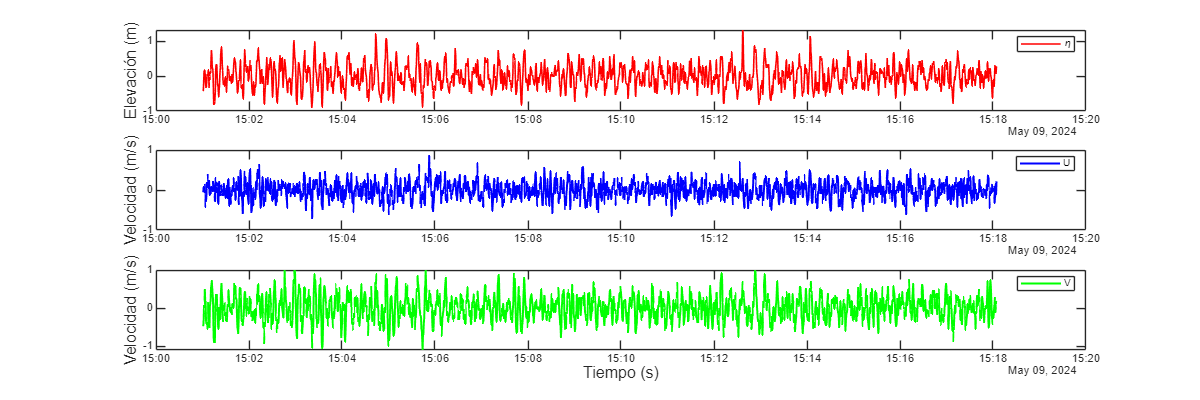

AST = data.burst_data.processed.ast(:, 1);
Pressure = data.burst_data.processed.pressure;
U = data.burst_data.processed.velocity_enu(:, 1);
V = data.burst_data.processed.velocity_enu(:, 2);

time = data.burst_data.time.burst_time;
fs = data.burst_data.general.fs;
ast_mean = data.burst_data.general.ast_mean;
cell_position = data.burst_data.general.cell_position;
mounting_height = data.burst_data.general.mounting_height;

h   = ast_mean + mounting_height;
z_p = -ast_mean;
z_v = cell_position - ast_mean;

plot_SUV(time, AST, U, V)

## Espectro frecuencial

Para el cálculo del espectro frecuencial, se usa la función *wsa_spectrum*. Por defecto el espectro se calcula con 16 grados de libertad y ventana de Hanning. Para el presente caso se indican 64 grados de libertad.

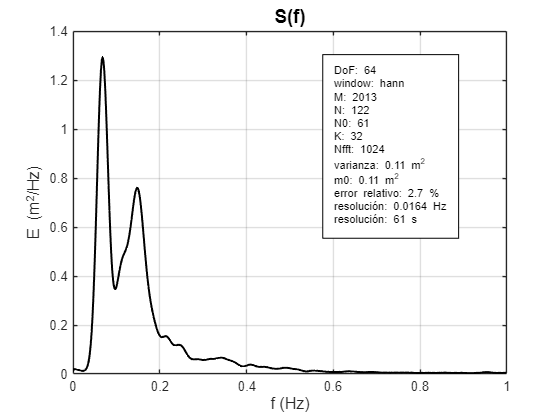

[out_Spec, info_Spec] = wsa_spectrum(AST, fs, 'DoF', 64);
f = out_Spec.f;
S = out_Spec.S;

figure; plot_spec(f, S, info_Spec)

## Parámetros espectrales

Para la estimación de los parámetros espectrales se usa la función *wsa_spectral_parameters*, la cual acepta los vectores *f* y *S* o el struct *out_Spec*. En el struct de resultados se guardan los parámetros correspondientes a banda total del espectro frecuencial.

out_Spec_Params = wsa_spectral_parameters(out_Spec)

out_Spec_Params = struct with fields:
                       m0: 0.1144
                       m1: 0.0182
                       m2: 0.0050
                       m4: 0.0014
                  eta_rms: 0.3382
                     Hrms: 0.9566
                      Hm0: 1.3542
                     Tm01: 6.2908
                     Tm02: 4.8039
                       Tp: 14.6286
                       fp: 0.0684
                        v: 0.8455
                       Qp: 1.0593
              band_limits: [0 0.9980]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0 0.9980]
           source_spectra: [1×1 struct]


Los parámetros correspondientes a las bandas por defecto se pueden encontrar en el substruct *bands*

ig_Spec = out_Spec_Params.bands.ig;
swell1_Spec = out_Spec_Params.bands.swell1;
swell2_Spec = out_Spec_Params.bands.swell2;
swell_Spec = out_Spec_Params.bands.swell;
wind_Spec = out_Spec_Params.bands.wind;

## Espectro direccional

El espectro direccional se puede estimar con la función *wsa_dirspectrum*, la cual recibe tres señales correspondientes a las tres direcciones ortogonales del plano.

Métodos disponibles:

- PUV : presion y velocidades horizontales.

- SUV : elevacion superficial y velocidades horizontales.

- HPR : heave, pitch y roll.

Para este ejemplo, se usa elevación de la superficie libre en Z, velocidad orbital X (Este) y velocidad orbital Y (Norte).

El método SUV requiere que se indiquen los parametros *z_v* y *h*; caso contrario se presenta un error. Por defecto el espectro direccional se calcula con 64 grados de libertad y 180 divisiones angulares.

[out_DirSpec, info_DirSpec] = wsa_dirspectrum(AST, U, V, fs, 'SUV', ...
                                             'z_v', z_v, ...
                                             'h', h);

El struct *out_DirSpec* contiene 2 substructs: Fourier y MEM. Cada uno de estos corresponde a resultados de los métodos de Serie de Fourier Truncada (TFS) y Método de Máxima Entropía de Lygre & Krogstad (MEM-I). Para el presente ejemplo se muestran los resultados MEM.

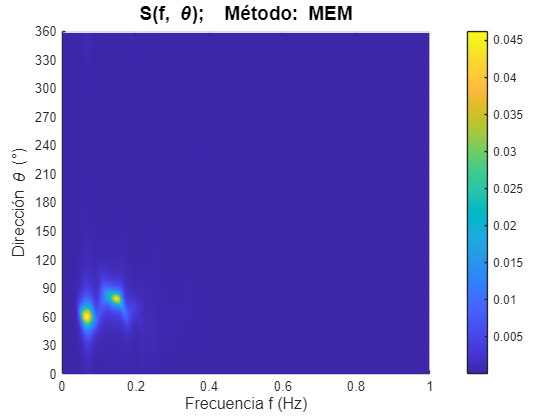

f = out_DirSpec.MEM.f;
theta = out_DirSpec.MEM.theta;
E = out_DirSpec.MEM.E;

xdir_out = 'reverse';   %Orientacion del eje de direcciones. 
DirMethod = 'MEM';      %Para el título unicamente.
figure; plot_DirSpec(f, theta, E, xdir_out, DirMethod)

## Parámetros direccionales

Para la estimación de los parámetros espectrales se usa la función *wsa_directional_parameters*, la cual acepta los vectores *f y S*, así como los coeficientes de Fourier *a1*, y *b1*; adicionalmente se puede indicar también los coeficientes *a2* y *b2*. También es posible pasar el struct *out_DirSpe*c.

En el struct de resultados se guardan los parametros correspondientes a la banda total del espectro direccional.

out_Dir_Params = wsa_directional_parameters(out_DirSpec.MEM)

out_Dir_Params = struct with fields:
                       fp: 0.0684
                       Tp: 14.6286
                    DirTp: 61.3594
                    SprTp: 28.3475
                  MeanDir: 69.1037
               MeanSpread: 40.2209
               f_mean_dir: [511×1 double]
                f_dir_spr: [511×1 double]
                       m0: 0.1144
                    a1_wa: 0.2688
                    b1_wa: 0.7040
                    R1_wa: 0.7536
              band_limits: [0.0020 0.9980]
             used_spectra: [1×1 struct]
                    bands: [1×1 struct]
         band_definitions: [1×1 struct]
    total_band_definition: [0.0020 0.9980]
           source_spectra: [1×1 struct]


Los parámetros correspondientes a las bandas por defecto se pueden encontrar en el substruct *bands.*

ig_DirSpec = out_Dir_Params.bands.ig;
swell1_DirSpec = out_Dir_Params.bands.swell1;
swell2_DirSpec = out_Dir_Params.bands.swell2;
swell_DirSpec = out_Dir_Params.bands.swell;
wind_DirSpec = out_Dir_Params.bands.wind;